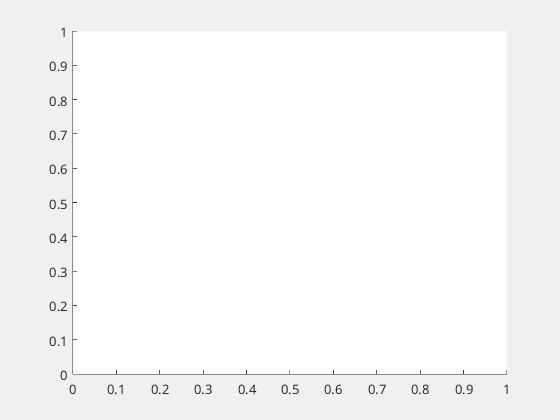

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


B = eye(3);
fig = figure( "Visible","on");
ax = axes(fig)

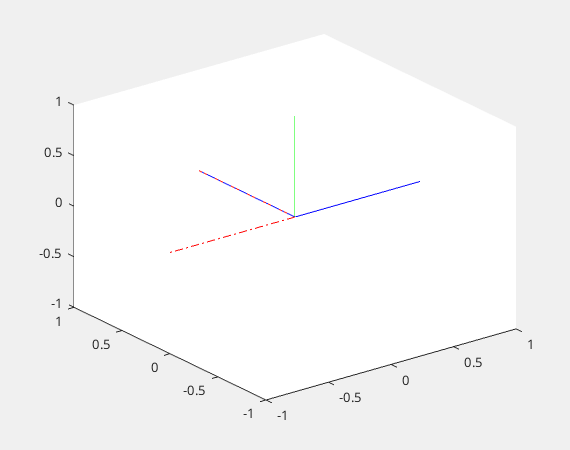

R = so3([0 0 0],"eul","ZYX").rotm;

Rb = R*B;
px = plot3(ax, [0 Rb(1,1)],[0 Rb(2,1)],[0 Rb(3,1)], 'b');
hold on
py = plot3(ax,[0 Rb(1,2)],[0 Rb(2,2)],[0 Rb(3,2)], 'r');
pz = plot3(ax, [0 Rb(1,3)],[0 Rb(2,3)],[0 Rb(3,3)], 'g');

ax.XLim = [-1 1];
ax.YLim = [-1 1];
ax.ZLim = [-1 1];


R = so3([pi/2 0 0],"eul","ZYX").rotm;

Rb = R*B;
px = plot3(ax, [0 Rb(1,1)],[0 Rb(2,1)],[0 Rb(3,1)], 'b-.');
py = plot3(ax,[0 Rb(1,2)],[0 Rb(2,2)],[0 Rb(3,2)], 'r-.');
pz = plot3(ax, [0 Rb(1,3)],[0 Rb(2,3)],[0 Rb(3,3)], 'g-.');

function update(fig,ax,B,q)

end